addpath('C:\Users\prakh\Documents\MATLAB\saved');  
rng(42);

%% --- Trajectory data---
filename = '09 - 2023-12-08-09-10-46_SRCC_Snow_speed_20250212170056.asc'; 
trajData = readtable(filename);
latVec_all = trajData.Var2;
lonVec_all = trajData.Var3;
nPointsAll = numel(latVec_all);

%% --- Base stations in lat and lon ---
BSpositions_latlon = [
    50.547614, 12.859297; % BS 1 
    50.53495, 12.872275;  % BS 2 
    50.54000, 12.86500;   % BS 3 (Between BS 1 & BS 2 for better triangulation)
    50.53650, 12.86000;   % BS 4 (Near BS 1 but at a different angle)
    50.54450, 12.87200;   % BS 5 (Close to BS 2)  
];
nBS = size(BSpositions_latlon, 1);

%% --- 3GPP Scenario Parameters ---
scenario = 'uma';
simParams = struct( ...
    'txPower',    40, ...  % [dBm]
    'txGain',     15, ...  % [dBi]
    'rxGain',     0, ...
    'systemLoss', 0, ...
    'fHz',        3.5e9, ...
    'fGHz',        3.5, ...
    'hBS',        25, ...
    'hUT',        1.5, ...
    'h',          5, ...  % avg building height for RMa
    'd0',         1 ...
);

% Calculate Breakpoint Distance d_bp for 3GPP
c = physconst('LightSpeed');
simParams.d_bp = (4 * (simParams.hBS - 1) * (simParams.hUT - 1) * simParams.fHz) / c;
fprintf('Breakpoint distance d_bp = %.2f m\n', simParams.d_bp);

Breakpoint distance d_bp = 560.39 m



%% --- Compute Minimum Distance to Base Stations ---
% For every trajectory point, find the minimum distance to any base station
minDistArray = zeros(nPointsAll, 1);
for i = 1:nPointsAll
    distsToAllBS = haversine([latVec_all(i), lonVec_all(i)], BSpositions_latlon);
    minDistArray(i) = min(distsToAllBS);
end

%% --- Filter Points Within Defined Coverage Range ---
maxRange_m = 2000; %metres
inCoverageMask = (minDistArray <= maxRange_m);

latVec_inRange = latVec_all(inCoverageMask);
lonVec_inRange = lonVec_all(inCoverageMask);
nPointsIn = sum(inCoverageMask);

fprintf('Kept %d points (%.1f%%) within %.1f km of at least one BS.\n', ...
    nPointsIn, 100*nPointsIn/nPointsAll, maxRange_m/1000);

Kept 3250 points (20.7%) within 2.0 km of at least one BS.



%% --- Compute RSSI using 3GPP Standards for In-Range Points ---
rssiMatrix_in = zeros(nPointsIn, nBS);
for i = 1:nPointsIn
    tgtPos = [latVec_inRange(i), lonVec_inRange(i)];  % user lat/lon
    for b = 1:nBS
        anchorPos = BSpositions_latlon(b, :);
        [rssiVal, ~] = calculateRSSI_3GPP(anchorPos, tgtPos, simParams, scenario);
        rssiMatrix_in(i, b) = rssiVal;
    end
end

% Choose the best RSSI for every Traj point
rssiVec_in = max(rssiMatrix_in, [], 2);

%% --- Invert RSSI to Estimate Distance ---
estDistMatrix_in = zeros(nPointsIn, nBS);
trueDistMatrix_in   = zeros(nPointsIn, nBS); % true dist using haversine for estimated ranges comparison

for i = 1:nPointsIn
    tgtPos = [latVec_inRange(i), lonVec_inRange(i)];    
    for b = 1:nBS
        anchorPos = BSpositions_latlon(b, :);
        d2D = haversine(tgtPos, anchorPos); %true 2D haversine distance to calculate if it is LOS/NLOS
        trueDistMatrix_in(i,b) = d2D;
        estDistMatrix_in(i, b) = rssi2distance_LogNormal(rssiMatrix_in(i, b), simParams, scenario, d2D);
    end
end

%comparing if estimated and true ranges make sense
diffDist = estDistMatrix_in - trueDistMatrix_in;
absErrDist = abs(diffDist); 

%% --- Initial Estimate for RLS estimator using Least Squares---
anchorPos2D = [BSpositions_latlon(:,1)'; BSpositions_latlon(:,2)'];
truePosMatrix_in = [latVec_inRange'; lonVec_inRange'];

[estPosLS_in, rmseLS_in, ~] = estimatePositionUsingLS_batchVectorized( ...
    anchorPos2D, estDistMatrix_in, truePosMatrix_in);

avgRMSE_LS_in = mean(rmseLS_in);
fprintf('Mean Initial guess RMSE (In-Range Only): %.2f m\n', avgRMSE_LS_in);

Mean Initial guess RMSE (In-Range Only): 268063288535.39 m


minRMSE_LS_in = min(rmseLS_in);
fprintf('Min Initial guess RMSE (In-Range Only): %.2f m\n', minRMSE_LS_in);

Min Initial guess RMSE (In-Range Only): 999714.18 m



%% --- Refine using RLS ---
nPointsIn = size(estPosLS_in, 2);
rlsEstimates_in = zeros(2, nPointsIn);
rmseRLS_in      = zeros(1, nPointsIn);
resnormCells_in = cell(1, nPointsIn);
rmseIterCells_in= cell(1, nPointsIn);

for i = 1:nPointsIn
    observedRanges_i = estDistMatrix_in(i, :);
    tgtpos2D_i       = truePosMatrix_in(:, i);
    lsInit_i = estPosLS_in(:, i); %LS initial guess for RLS estimator

    [mu_i, rmse_i, resnorm_vec_i, rmse_vec_i] = ...
        recursiveLeastSquares(anchorPos2D, observedRanges_i, tgtpos2D_i, lsInit_i);

    rlsEstimates_in(:, i) = mu_i;
    rmseRLS_in(i)         = rmse_i;
    resnormCells_in{i}    = resnorm_vec_i;
    rmseIterCells_in{i}   = rmse_vec_i;
end

avgRMSE_RLS_in = mean(rmseRLS_in);
fprintf('Mean RLS RMSE (In-Range): %.2f m\n', avgRMSE_RLS_in);

Mean RLS RMSE (In-Range): 2337.01 m


minRMSE_RLS_in = min(rmseRLS_in);
fprintf('Min RLS RMSE (In-Range): %.2f m\n', minRMSE_RLS_in);

Min RLS RMSE (In-Range): 183.51 m


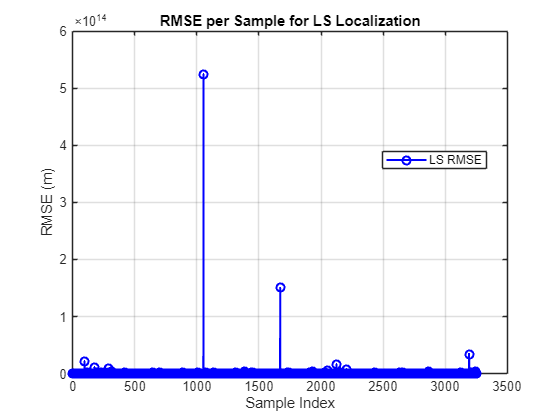


%% --- Plotting and Visualizing Results ---
% RMSE per sample for LS Initial estimate
figure('Color','white','Name','RMSE per Sample - LS');
plot(1:length(rmseLS_in), rmseLS_in, 'bo-', 'LineWidth', 1.5);
xlabel('Sample Index');
ylabel('RMSE (m)');
title('RMSE per Sample for LS Localization');
grid on;
legend('LS RMSE', 'Location', 'best');

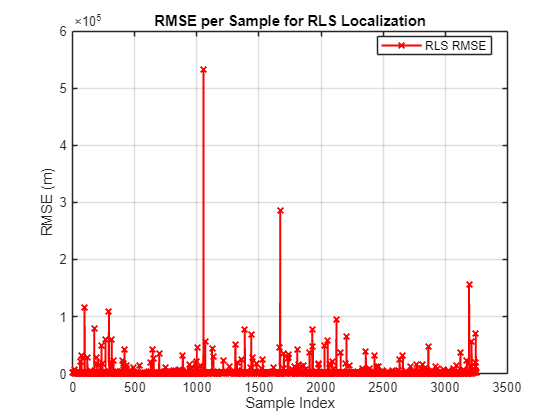


%% RMSE per Sample for RLS
figure('Color','white','Name','RMSE per Sample - RLS');
plot(1:length(rmseRLS_in), rmseRLS_in, 'rx-', 'LineWidth', 1.5);
xlabel('Sample Index');
ylabel('RMSE (m)');
title('RMSE per Sample for RLS Localization');
grid on;
legend('RLS RMSE', 'Location', 'best');

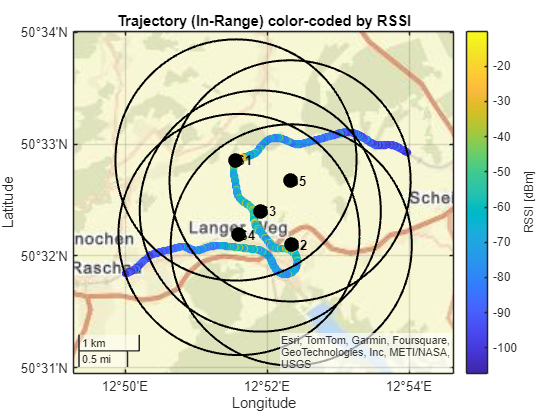



%% --- Geoaxes plot ---
% Plot In-Range Trajectory Color-coded by RSSI
figure('Color','white','Name','In-Range Coverage');
gx = geoaxes;
geobasemap(gx, 'streets');
hold(gx, 'on');

geoscatter(gx, latVec_inRange, lonVec_inRange, 30, rssiVec_in, 'filled');
cb = colorbar;
cb.Label.String = 'RSSI [dBm]';
title(gx, 'Trajectory (In-Range) color-coded by RSSI');

% Base stations as black circles
geoscatter(gx, BSpositions_latlon(:,1), BSpositions_latlon(:,2), 120, 'k', 'filled');
for b = 1:nBS
    text(gx, BSpositions_latlon(b,1), BSpositions_latlon(b,2), sprintf('S%d', b),...
        'FontWeight', 'bold', 'Color', 'k');
end

% Coverage circles for each base station
nCirclePoints = 100;
theta = linspace(0, 360, nCirclePoints);

for i = 1:nBS
    centerLat = BSpositions_latlon(i, 1);
    centerLon = BSpositions_latlon(i, 2);
    circleLat = zeros(1, nCirclePoints);
    circleLon = zeros(1, nCirclePoints);
    for j = 1:nCirclePoints
        [circleLat(j), circleLon(j)] = endpointHaversine(centerLat, centerLon, maxRange_m, theta(j));
    end
    geoplot(gx, circleLat, circleLon, 'k-', 'LineWidth', 1.5);
end

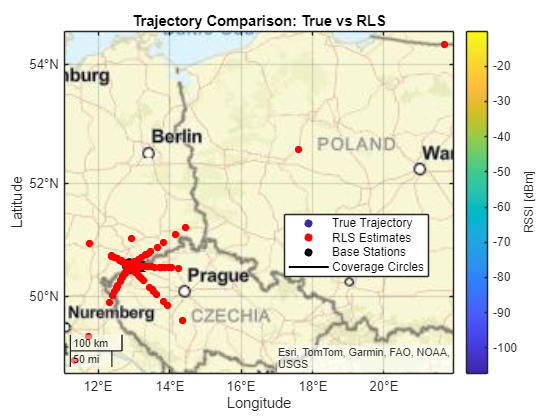


%% --- Comparison Plot: True Trajectory vs RLS Estimates ---
figure('Color','white','Name','RLS Estimated Trajectory');
gx = geoaxes;
geobasemap(gx, 'streets');
hold(gx, 'on');

% true color-coded RSSI trajectory
hTrue = geoscatter(gx, latVec_inRange, lonVec_inRange, 30, rssiVec_in, 'filled');
cb = colorbar;
cb.Label.String = 'RSSI [dBm]';
title(gx, 'Trajectory Comparison: True vs RLS');

% Base stations
hBS = geoscatter(gx, BSpositions_latlon(:,1), BSpositions_latlon(:,2), 120, 'k', 'filled');
for b = 1:nBS
    text(gx, BSpositions_latlon(b,1), BSpositions_latlon(b,2), sprintf('S%d', b),...
         'FontWeight', 'bold', 'Color', 'k');
end

% Plot the coverage circles for each base station
hCoverage = gobjects(nBS,1); % Preallocate graphic object array for legend
for i = 1:nBS
    % Get center point for the BS
    centerLat = BSpositions_latlon(i, 1);
    centerLon = BSpositions_latlon(i, 2);

    circleLat = zeros(1, nCirclePoints);
    circleLon = zeros(1, nCirclePoints);
    for j = 1:nCirclePoints
        [circleLat(j), circleLon(j)] = endpointHaversine(centerLat, centerLon, maxRange_m, theta(j));
    end
    hCoverage(i) = geoplot(gx, circleLat, circleLon, 'k-', 'LineWidth', 1.5);
end

% Convert RLS estimates from local XY back to lat/lon using BS 1 as reference
latRef = BSpositions_latlon(1,1);
lonRef = BSpositions_latlon(1,2); 
[estLat, estLon] = localXY2LatLon(rlsEstimates_in(1,:), rlsEstimates_in(2,:), latRef, lonRef);

% Overlay the RLS estimations in red
hRLS = geoscatter(gx, estLat, estLon, 30, 'r', 'filled');

legend(gx, [hTrue, hRLS, hBS, hCoverage(1)], ...
       {'True Trajectory', 'RLS Estimates', 'Base Stations', 'Coverage Circles'}, ...
       'Location', 'best');

%coverage plot
% anchorpos3D = [anchorPos2D; zeros(1, size(anchorPos2D, 2))];
% 
% numBS = size(anchorpos3D, 2);
% txs   = txsite.empty;  % preallocate array of txsite objects
% 
% %power in watts
% P_Watt = 10^((simParams.txPower - 30)/10);
% 
% for iBS = 1:numBS
%     txs(iBS) = txsite("Name",          sprintf("BS_%d", iBS), ...
%                       "Latitude",      anchorpos3D(1, iBS), ...
%                       "Longitude",     anchorpos3D(2, iBS), ...
%                       "AntennaHeight", simParams.hBS, ...
%                       "TransmitterPower", P_Watt, ...       % in Watts or dBm (see note below)
%                       "TransmitterFrequency", simParams.fHz, ...
%                       "Antenna",       "isotropic");
% end
% 
% nPoints = length(latVec_inRange);
% rxs = rxsite.empty(nPoints, 0);
% 
% for i = 1:nPoints
%     rxs(i) = rxsite( ...
%         "Name",            sprintf("User%d", i), ...
%         "Latitude",        latVec_inRange(i), ...
%         "Longitude",       lonVec_inRange(i), ...
%         "AntennaHeight",   simParams.hUT, ...
%         "Antenna",         "isotropic" ...
%         );
% end
% 
% viewer = siteviewer('Basemap', 'satellite'); 
% show(txs);  % show all transmitters
% show(rxs(1));   % show receiver site
% 
% for b = 1:numBS
%     los(txs(b), rxs(1));
% end
% 
% weatherpm = propagationModel("gas") + propagationModel("rain");
% pm = propagationModel("longley-rice") + weatherpm;
% 
% rxPowerMatrix = sigstrength(rxs, txs, pm);
% 
% coverage(txs, ...
%     'PropagationModel',       pm, ...
%     'ReceiverGain',           simParams.rxGain, ...            % set to 0 if no extra gain
%     'SignalStrengths',        -130:5:-40, ...                  % Example levels in dBm
%     'ReceiverAntennaHeight',  simParams.hUT, ...
%     'MaxRange',               5000);  % e.g. 5km coverage

%% --- RSSI Calculation - 3GPP Models ---
function [rssi, pathLoss_dB] = calculateRSSI_3GPP(anchorPos, tgtPos, simParams, scenario)
% calculateRSSI_3GPP Computes the received signal strength (RSSI) for a given base station and target.
%   This function calculates the RSSI by taking into account path loss, shadowing,
%   and small-scale fading (using either Rician or Rayleigh fading) based on 3GPP models.
%
%   Inputs:
%     anchorPos : [1x2] Base station coordinates [lat, lon] (in meters)
%     tgtPos    : [1x2] Target/user coordinates [lat, lon] (in meters)
%     simParams : Structure containing simulation parameters (e.g., txPower, txGain, rxGain, etc.)
%     scenario  : A string specifying the environment ('uma', 'rma', or 'inh')
%
%   Outputs:
%     rssi        : Final calculated RSSI in dBm
%     pathLoss_dB : Combined path loss in dB (including shadowing, before applying fading)

    % Speed of light (m/s)
    c = physconst('LightSpeed');
    
    % -- Compute 2D and 3D Distances --
    d2D = haversine(tgtPos, anchorPos);
    d3D = sqrt(d2D^2 + (simParams.hBS - simParams.hUT)^2);
    
    % -- Determine LOS/NLOS --
    P_LOS = calculate_LOS_probability(d2D, scenario, simParams.hUT);
    isLOS = (rand() < P_LOS);
    
    % -- Calculate Path Loss Depending on LOS/NLOS --
    if isLOS
        PL = getLOSpathLoss(scenario, d2D, d3D, simParams.d_bp, simParams.fHz/1e9, simParams.hBS, simParams.hUT, simParams.h);
        shadowSigma = getShadowSigma(scenario, true);
    else
        [PL_LOS, PL_NLOS] = getNLOSpathLoss(scenario, d2D, d3D, simParams.d_bp, simParams.fHz/1e9, simParams.hBS, simParams.hUT, simParams.h);
        PL = max(PL_LOS, PL_NLOS);
        shadowSigma = getShadowSigma(scenario, false);
    end
    
    % -- Add Log-Normal Shadowing --
    shadowing = normrnd(0, shadowSigma);
    % shadowing = 0;
    pathLoss_dB = PL + shadowing;
    
        
    % Apply small-scale fading:
    % Rician fading if LOS
    if isLOS
        K = 10;
        h_los = sqrt(K/(K+1));  
        h_nlos = sqrt(1/(2*(K+1)))*(randn() + 1j*randn());
        h_fading = h_los + h_nlos;
    else
        % Rayleigh fading if NLOS.
        h_fading = (1/sqrt(2))*(randn() + 1j*randn());
    end
    fadingPower_dB = 10*log10(abs(h_fading)^2);
    
    % RSSI calculation
    rssi = simParams.txPower + simParams.txGain + simParams.rxGain ...
           - pathLoss_dB - simParams.systemLoss + fadingPower_dB;
end

%% ------------------------------------------------------------------------
%% --- LOS Probability Calculation ---
function P_LOS = calculate_LOS_probability(d2D, scenario, hUT)
% calculate_LOS_probability Returns the probability of a LOS link based on 3GPP TR 38.901.
%
%   Inputs:
%     d2D      : 2D distance between transmitter and receiver (meters)
%     scenario : Scenario type ('uma', 'rma', 'inh')
%     hUT      : User terminal height (meters)
%
%   Output:
%     P_LOS : Probability of a LOS connection (value between 0 and 1)

    switch lower(scenario)
        case 'uma'
            if d2D <= 18
                P_LOS = 1;
            else
                C_hUT = 0;
                if (13 < hUT) && (hUT <= 23)
                    C_hUT = ((hUT - 13)/10)^1.5;
                end
                P_LOS = (18/d2D + exp(-d2D/63) * (1 - 18/d2D)) * (1 + C_hUT * (5/4) * (d2D/100)^3 * exp(-d2D/150));
            end
        case 'rma'
            if d2D <= 10
                P_LOS = 1;
            else
                P_LOS = exp(-((d2D - 10)/1000));
            end
        case 'inh'
            if d2D <= 1.2
                P_LOS = 1;
            else
                P_LOS = exp(-(d2D - 1.2)/4.7);
                P_LOS = max(min(P_LOS, 1), 0);
            end
        otherwise
            P_LOS = 0.5;
    end
end

%% ------------------------------------------------------------------------
%% --- LOS Path Loss Model ---
function PL_LOS = getLOSpathLoss(scenario, d2D, d3D, d_bp, fGHz, hBS, hUT, h)
% getLOSpathLoss Computes the LOS path loss (in dB) as specified by 3GPP TR 38.901.
%
%   Inputs:
%     scenario : Environment type ('uma', 'rma', or 'inh')
%     d2D      : 2D distance (m)
%     d3D      : 3D distance (m)
%     d_bp     : Breakpoint distance (m)
%     fGHz     : Carrier frequency (GHz)
%     hBS      : Base station height (m)
%     hUT      : User terminal height (m)
%     h        : Average building height for RMa(m)
%
%   Output:
%     PL_LOS : LOS path loss in dB
    switch lower(scenario)
        case 'uma'
            if d2D <= d_bp
                PL_LOS = 28 + 22*log10(d3D) + 20*log10(fGHz);
            else
                PL_LOS = 28 + 40*log10(d3D) + 20*log10(fGHz) - 9*log10(d_bp^2 + (hBS-hUT)^2);
            end
        case 'rma'
            if d2D <= d_bp
                PL_LOS = 20*log10(40*pi*d2D*fGHz/3) + min(0.03*h^(1.72),10)*log10(d3D) - min(0.044*h^(1.72),14.77) + 0.002*log10(h)*d3D;
            else
                PL_LOS = 20*log10(40*pi*d2D*fGHz/3) + min(0.03*h^(1.72),10)*log10(d3D) - min(0.044*h^(1.72),14.77) + 0.002*log10(h)*d3D + 40*log10(d3D/d_bp);
            end
        case 'inh'
            PL_LOS = 32.4 + 17.3*log10(d3D) + 20*log10(fGHz);
        otherwise
            PL_LOS = 0;
    end
end

%% ------------------------------------------------------------------------
%% --- NLOS Path Loss Model ---
function [PL_LOS, PL_NLOS] = getNLOSpathLoss(scenario, d2D, d3D, d_bp, fGHz, hBS, hUT, h)
% getNLOSpathLoss Computes the non-line-of-sight (NLOS) path loss as per 3GPP TR 38.901.
%
%   This function returns both the LOS and NLOS estimates, and the final
%   loss is taken as the maximum of the two.
%
%   Inputs: (same as getLOSpathLoss)
%
%   Outputs:
%     PL_LOS  : LOS path loss (for reference)
%     PL_NLOS : NLOS path loss in dB

    PL_LOS = getLOSpathLoss(scenario, d2D, d3D, d_bp, fGHz, hBS, hUT, h);
    switch lower(scenario)
        case 'uma'
            PL_prime = 13.54 + 39.08*log10(d3D) + 20*log10(fGHz) - 0.6*(hUT - 1.5);
            PL_NLOS = max(PL_LOS, PL_prime);
        case 'rma'
            W = 20; % Average street width (m)
            PL_prime = 161.04 - 7.1*log10(W) + 7.5*log10(hBS) - (24.37 - 3.7*(hBS/hUT)^2)*log10(hUT) + (43.42 - 3.1*log10(hUT))*(log10(d3D)-3) + 20*log10(fGHz) - 0.6*(hUT-1.5);
            PL_NLOS = max(PL_LOS, PL_prime);
        case 'inh'
            PL_prime1 = 38.3*log10(d3D) + 17.3 + 24.9*log10(fGHz);
            PL_prime2 = 32.4 + 20*log10(fGHz) + 31.9*log10(d3D);
            PL_NLOS = max([PL_LOS, PL_prime1, PL_prime2]);
        otherwise
            PL_NLOS = PL_LOS;
    end
end

%% ------------------------------------------------------------------------
%% --- Shadowing Standard Deviation ---
function sigmaVal = getShadowSigma(scenario, isLOS)
% getShadowSigma Returns the standard deviation (in dB) used for log-normal shadowing.
%
%   This value depends on both the environment and whether the link is LOS.
%
%   Inputs:
%     scenario : Environment type ('uma', 'rma', 'inh')
%     isLOS    : Boolean flag (true for LOS, false for NLOS)
%
%   Output:
%     sigmaVal : Standard deviation in dB

    switch lower(scenario)
        case 'uma'
            sigmaVal = isLOS * 4 + (~isLOS) * 6;
        case 'rma'
            sigmaVal = isLOS * 4 + (~isLOS) * 8;
        case 'inh'
            sigmaVal = isLOS * 3 + (~isLOS) * 8;
        otherwise
            sigmaVal = 5;
    end
end

%% ------------------------------------------------------------------------
%% --- RSSI inversion to estimate distances ---
function d_est = rssi2distance_LogNormal(rssi, simParams, scenario, d2D)
% rssi2distance_LogNormal Estimates the distance based on a log-normal path loss model.
%
%   This function inverts the path loss equation:
%       RSS = P0 - 10*β*log10(d/d0) + n,
%   where n is a shadowing term.
%
%   Inputs:
%     rssi      : Measured RSS (in dBm)
%     simParams : Structure of simulation parameters (txPower, txGain, etc.)
%     scenario  : Environment type ('uma', 'rma', or 'indoor')
%     d2D       : The current 2D distance between transmitter and receiver (meters)
%
%   Output:
%     d_est : Estimated distance (in meters)
%
%   Note: In this inversion, the random shadowing is already embedded in the RSS measurement.
    % Determine the LOS condition using the LOS probability.

    P_LOS = calculate_LOS_probability(d2D, scenario, simParams.hUT);
    isLOS = (rand() < P_LOS);
    % 1. Choose beta based on the scenario:
    switch lower(scenario)
        case 'uma'
          if isLOS
               beta = 2.2;
          else
               beta = 3.5;
           end
        case 'rma'
            if isLOS
               beta = 2.0;
          else
                beta = 2.75;
           end
        otherwise
        beta = 3.0;
    end

    % Reference distance d0 (1m normally)
    if ~isfield(simParams, 'd0')
        simParams.d0 = 1;  % default to 1 m if not provided
    end
    d0 = simParams.d0;
    
    % -- Free-space path loss at the reference distance --
    %    FSPL(d0) = 32.45 + 20*log10(d0_km) + 20*log10(fMHz),
    %    where d0_km is d0 in kilometers.
    fMHz = simParams.fHz / 1e6;
    d0_km = d0 / 1000;
    PL0 = 32.45 + 20*log10(d0_km) + 20*log10(fMHz);
    
    % -- Expected received power at d0 --
    P0 = simParams.txPower + simParams.txGain + simParams.rxGain - simParams.systemLoss - PL0;
    
    sigma = getShadowSigma(scenario, isLOS);
    n = sigma * randn();
    
    % -- Invert the model to estimate distance --
    %    RSS = P0 - 10*β*log10(d/d0) + n  ==>  d = d0 * 10^((P0 - (RSS - n))/(10*β)).
    % Note: The term 'n' is already part of the measured RSS, so it's not explicitly subtracted here.
    d_est = d0 * 10^((P0 - (rssi))/(10*beta));
end

%% ------------------------------------------------------------------------
%% --- Helper fucntion to convert distaces while plottign ---
% helper function to pülot BS coverage circles
function [lat2, lon2] = endpointHaversine(lat1, lon1, d, bearing)

    % Convert inputs to radians
    R = 6371000; % Earth radius in meters
    lat1 = deg2rad(lat1);
    lon1 = deg2rad(lon1);
    bearing = deg2rad(bearing);

    % Calculate the endpoint lat/lon using Haversine
    lat2 = asin(sin(lat1) * cos(d/R) + cos(lat1) * sin(d/R) * cos(bearing));
    lon2 = lon1 + atan2(sin(bearing) * sin(d/R) * cos(lat1), cos(d/R) - sin(lat1) * sin(lat2));

    % Convert back to degrees
    lat2 = rad2deg(lat2);
    lon2 = rad2deg(lon2);
end

function [lat, lon] = localXY2LatLon(x, y, latRef, lonRef)
% LOCALXY2LATLON Convert local XY coordinates (meters) back to latitude/longitude (degrees).
%
%   [lat, lon] = localXY2LatLon(x, y, latRef, lonRef)
%
%   This function uses a simple equirectangular approximation valid
%   for relatively small distances from the reference point.
%
%   Inputs:
%       x      - local East coordinate in meters (can be scalar or vector)
%       y      - local North coordinate in meters (can be scalar or vector)
%       latRef - reference latitude in degrees (scalar)
%       lonRef - reference longitude in degrees (scalar)
%
%   Outputs:
%       lat - latitude in degrees (same size as x,y)
%       lon - longitude in degrees (same size as x,y)
%
%   Example:
%       % Suppose we have local coords x=3000m East, y=1000m North of (latRef=50, lonRef=8)
%       % Convert them back to lat/lon:
%       [lat, lon] = localXY2LatLon(3000, 1000, 50, 8);

    % Convert reference latitude to radians
    lat0 = deg2rad(latRef);

    % Approximate meters per degree of latitude/longitude
    mPerDegLat = 111320;           % ~111.32 km/deg
    mPerDegLon = 111320 * cos(lat0);

    % Convert back to lat/lon in degrees
    lat = latRef + (y ./ mPerDegLat);
    lon = lonRef + (x ./ mPerDegLon);
end

function d = haversine(latlon1, latlon2)
    R = 6371000; % Earth radius in meters
    lat1 = deg2rad(latlon1(1));
    lon1 = deg2rad(latlon1(2));
    lat2 = deg2rad(latlon2(:,1));
    lon2 = deg2rad(latlon2(:,2));
    
    dlat = lat2 - lat1;
    dlon = lon2 - lon1;
    
    a = sin(dlat/2).^2 + cos(lat1) .* cos(lat2) .* sin(dlon/2).^2;
    c = 2 * atan2(sqrt(a), sqrt(1-a));
    
    d = R * c;
end